# Three Node Network inversion with TAPAS

Read in Smith et al. (2011) network structure used in Frässle et al. (2018) to use as a template for your own DCM.

rng(2406,'twister')
temp = load('tapas-master/rDCM/test/DCM_LargeScaleSmith_model1.mat');
org_DCM = temp.DCM;

Create new DCM structure with fields needed by `tapas_rdcm_generate.m`

**What should you specify the input as for "resting state" data? **`tapas_rdcm_generate.m`** does need DCM.U to be specified and setting it to 0 creates flat timeseries at 0.**

% my_DCM.U.name = {'u1'};
% my_DCM.U.dt = 0.5/16;
% my_DCM.U.u = interp1(1:T, my_task_secs, 1:my_DCM.U.dt:T, "linear")'

Specify  true connectivity matrix.

my_DCM.Tp.A = [0 0.2 0; 0.4 0 0; 0 0.3 0]

my_DCM = struct with fields:
    Tp: [1×1 struct]


num_nodes = 3;
% num_inputs = 1;
% my_DCM.Tp.B = zeros(num_nodes, num_nodes, num_inputs)
% stim_node = 1;
% stim_mag = 0.5;
% my_DCM.Tp.C = zeros(num_nodes, num_inputs);
% my_DCM.Tp.C(stim_node) = stim_mag
my_DCM.Tp.D = []

my_DCM = struct with fields:
    Tp: [1×1 struct]


Specify constants that'll be used for the balloon model.

my_DCM.Tp.transit = normrnd(0, 0.1, [3, 1]);
my_DCM.Tp.decay = normrnd(0, 0.1, [3, 1]);
my_DCM.Tp.epsilon = -0.05;

A priori connectivity matrix set to full connectivity to see if it can correctly prune it to the true matrix given resting state data.

my_DCM.a = ones(num_nodes, num_nodes);

Specify the options for the rDCM analysis

options.SNR             = 3;
options.y_dt            = 0.5;
options.p0_all          = 0.15;  % single p0 value (for computational efficiency)
options.iter            = 100;
options.filter_str      = 5;
options.restrictInputs  = 1;

% run a simulation (synthetic) analysis
type = 's';

Generate BOLD timeseries using created DCM structure 

my_DCM = tapas_rdcm_generate(my_DCM, options, options.SNR);

Visualize simulated data. Does the above function create data in time or frequency space?

plot(my_DCM.y)

## Invert simulated data

my_DCM.n = num_nodes;
[output, options] = tapas_rdcm_estimate(my_DCM, type, options, 2);

## Signal frequency analysis practice

Convolving with a gaussian filter in time space vs. applying gaussian filter in frequency space and inverse FFT to time space.

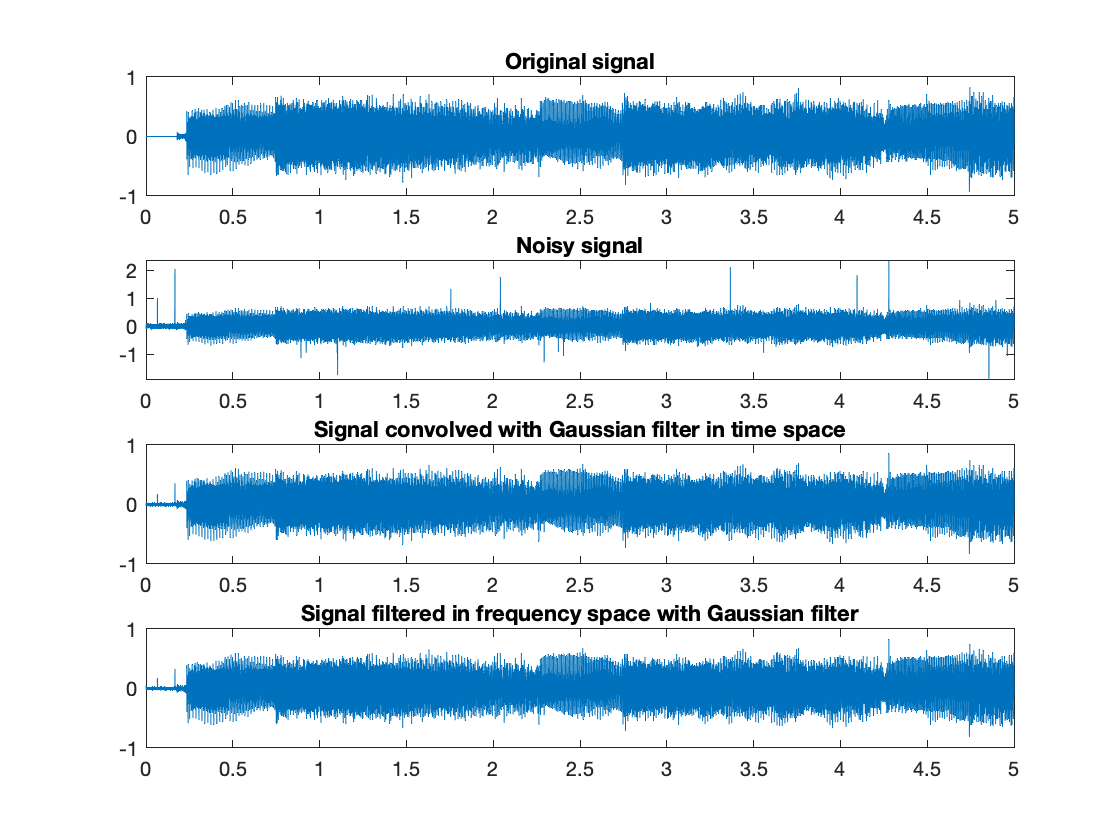

Fs = 44100;
T = 5;
t = [0:1/Fs:T];
[yg, Fsg] = audioread("/Applications/MATLAB_R2020b.app/toolbox/audio/samples/RockGuitar-16-96-stereo-72secs.flac");
ygresamp = interp1([0:1/Fsg:(length(yg)-1)/Fsg],yg(:,1),t);

sprate = 10;
sigma = 0.03;
spnoise = saltpeppernoise(sprate,t,Fs);
wnoise = sigma*randn(size(t));

ygnoisy = ygresamp + spnoise + wnoise;

%Convolving with Gaussian filter
W = 13; %window size
sigma = W/6; %for Gaussian filter
gaussianfilter = fspecial('gaussian', [1, W], sigma);
yggaus = conv(ygnoisy, gaussianfilter, 'same');

%Apply Gaussian filter in frequency space
[yfft, f] = myfft(ygnoisy, Fs);
gsigma = 3000;
H = exp(-f.^2/(2*gsigma^2)); %Gaussian filter in frequency space
yfftfilt = yfft'.*H; %Applying the filter in frequency space
yglp = myifft(yfftfilt, f, Fs);

subplot(4, 1, 1)
plot(t, ygresamp)
title('Original signal')

subplot(4, 1, 2)
plot(t, ygnoisy)
title('Noisy signal')

subplot(4, 1, 3)
plot(t, yggaus)
title('Signal convolved with Gaussian filter in time space')

subplot(4, 1, 4)
plot(t, flipud(yglp))
title('Signal filtered in frequency space with Gaussian filter')

Why is `tapas_rdcm_generate.m` convolving signal using the loop below?

They convolve the neural signal with the HRF in frequency space and then ifft to convert back into time space.

**But why do they then only take the middle chunk of the signal tripled in length?**

% for i = 1:nr
%     tmp = ifft(fft(x(:,i)).*fft([h; zeros(N*3-length(h),1)]));
%     y(:,i) = tmp(N+1:2*N);
% end

## Effects of filtering

% What is the effect of the filtering?